# Clustering Human Activity Sensor Data

Human activity sensor data contains observations derived from sensor measurements taken from smartphones worn by people while doing different activities (walking, standing, sitting). The goal of this analysis is to identify clusters of similar activities and what they may represent. 

The dataset can be found [here](https://archive.ics.uci.edu/ml/datasets/human+activity+recognition+using+smartphones):

`Dataset Courtesy:`` Davide Anguita, Alessandro Ghio, Luca Oneto, Xavier Parra and Jorge L. Reyes-Ortiz. A Public Domain Dataset for Human Activity Recognition Using Smartphones. 21th European Symposium on Artificial Neural Networks, Computational Intelligence and Machine Learning, ESANN 2013. Bruges, Belgium 24-26 April 2013. `

## Load data

The data is saved in a MAT file from a previous exercise. We will use buffered data with extracted features as our starting point. 

clear variables
addpath(genpath(pwd));
%addpath("./04-HelperFiles");
rng(1);
if ~exist('trainFeatures')
    % load features from (previously saved) file
    load('extractedFeatures','trainFeatures');
end
labels = trainFeatures.Properties.VariableNames;
sensorData = table2array(trainFeatures(:,1:end-1));

## Visualize data using dimensionality reduction

This dataset has 66 columns or variables making it a high-dimensional dataset that is inherently hard to visualize. We must therefore choose certain columns of data or reduce the number of dimensions. We looked at feature selection in the previous exercise. Here we will explore PCA used for feature transformation. 

[Principal component analysis (PCA)](matlab:web(fullfile(docroot, 'stats/principal-component-analysis-pca.html'))) is one of the most popular methods of reducing the dimensionality of the data by computing orthogonal dimensions of maximum variance of the dataset. In this case, note that a few principal components capture a good portion of the variance in the dataset but that variance captured doesn't grow very fast with an increase in the number of principal components. 

This pareto chart shows which percentage of variability in the data is explained by the first couple principal components.

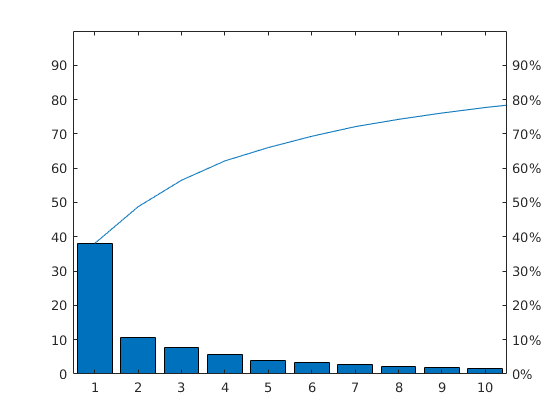

[pcs,score,latent,~,pexp] = pca(sensorData);
pareto(pexp)

**Visualize clustering using reduced data**

We can use a heatmap the scores (loadings) of each observation for a few principal components. One can start to identify features are relevant to the principal components, and which receive little to no load in any - thus making them candidates for feature selection (or rather, elimination).

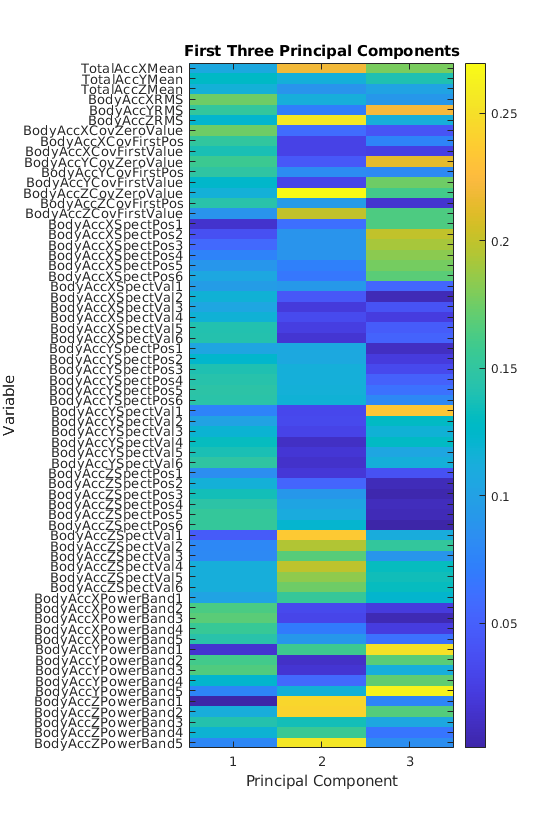

f = figure;
f.Position = f.Position.*[1 1 1 2];
imagesc(abs(pcs(:,1:3)))
colorbar
yticks(1:66)
yticklabels(labels(1:end-1))
xticks(1:3)
xlabel('Principal Component')
ylabel('Variable')
title('First Three Principal Components')

## Try different clustering algorithms 

Clustering is a form of unsupervised learning technique. The purpose of clustering is to identify natural groupings of data from a large data set to produce a concise representation based on common characteristics.  

The definition of a `cluster` is imprecise and the best definition depends on the nature of the data and the desired results.The common clustering techniques discussed in literature include distance-based, probability-based and density-based methods. 

In this example, we will explore 3 different kinds of clustering techniques.

- [K-Means](matlab: web(fullfile(docroot, 'stats/k-means-clustering.html'))) : K-Means partitions data into k mutually exclusive clusters, and returns the index of the cluster to which it has assigned each observation. *k*-means clustering is often more suitable for large amounts of data.

- [Hierarchical Clustering](matlab:web(fullfile(docroot, 'stats/hierarchical-clustering.html'))): Hierarchical Clustering groups data over a variety of scales by creating a cluster tree or dendrogram. The tree is not a single set of clusters, but rather a multilevel hierarchy, where clusters at one level are joined as clusters at the next level. This allows you to decide the level or scale of clustering that is most appropriate for your application. 

- [Gaussian Mixture Models](matlab:web(fullfile(docroot, 'stats/clustering-using-gaussian-mixture-models.html'))): Gaussian Mixture Models are a soft clustering method which form clusters by representing the probability density function of observed variables as a mixture of multivariate normal densities. The posterior probabilities for each point indicate that each data point has some probability of belonging to each cluster. Gaussian mixture modeling may be more appropriate when clusters have different sizes and correlation within them.

In the section below vary the number of clusters and try the different algorithms to see how the results change. Which one would you pick? How would you interpret the results knowing this is sensor data coming for different human activities.  

Note: We use the sensor data to find the clusters, but use the PCA scores to visualize our clusters. 

**To do: Change the number of clusters and/or the clustering method to see the different resulting clusters**

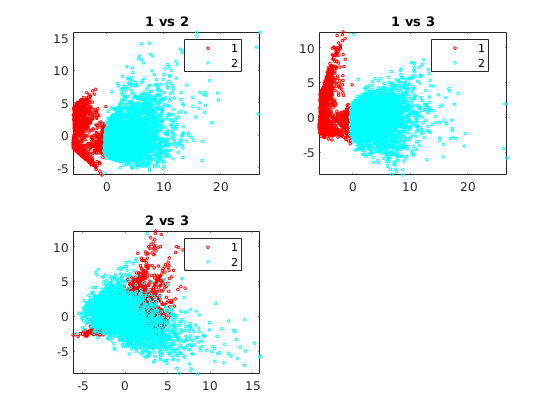

% TO DO: Vary the number of clusters. Identify which method and nClust
% "best" separates the classes
nClust = 2; 
method = 'k-means';

switch method 
    case 'k-means'
        cidx = kmeans(sensorData,nClust,'distance','cosine','replicates',5);
    case 'hierarchical'
        cidx = clusterdata(sensorData, 'maxclust', nClust, 'distance' , 'correlation',...
    'linkage', 'complete');
    case 'GMM'
        gmobj = fitgmdist(sensorData,nClust,'Replicates',5,'CovarianceType','diagonal');
        cidx = cluster(gmobj,sensorData);
end

% View the clusters 
pairscatter(score(:,1:3), [], cidx);

## Determine the optimal number of clusters

The [evalclusters](matlab:web(fullfile(docroot, 'stats/evalclusters.html'))) function can be used to evaluate a clustering algorithm like kmeans for different number of clusters and calculate a metric that can be used to determine the optimal number of clusters. 

***This does not necessarily mean that it is the best number of clusters to use***.  The best number of clusters to use depends on the insights that a particular clustering provides.

ev = evalclusters(sensorData,'gmdistribution','silhouette','KList',2:6)

ev =   SilhouetteEvaluation with properties:

    NumObservations: 6873
         InspectedK: [2 3 4 5 6]
    CriterionValues: [0.4019 0.2682 0.3250 0.2339 0.2860]
           OptimalK: 2


So what's the optimal number of clusters? Go back and look at the confusion matrices of module 02. Which categories would you collapse to obtain the optimal number of clusters determined above?

**TO DO: Modify the data used on module 02 to reflect the optimal number of categories, and retrain some models. How did this reframing of the classification task change the playing field? **

## Find discriminative features

It can be helpful to find a small set of features that can highly discriminate between clusters. This can reduce the dimensionality of the problem and help in interpreting the clustering results. To do that, we use a function that computes a paired t test for each feature for each cluster pair and uses the test statistic to rank the features.

[featIdx, pair] = featureScore(sensorData, cidx, 5);

disp('Top 5 features for separation of clusters:');
for i = 1:size(pair,1)
    fprintf('%d and %d: ', pair(i,1), pair(i,2));
    fprintf('%s, ', labels{featIdx(i,:)});
    fprintf('\n');
end

We can visually confirm the separation of clusters by the feature that most often occurs in the top 3 list using a boxplot. On each box, the central mark indicates the median, and the bottom and top edges of the box indicate the 25th and 75th percentiles, respectively. The whiskers extend to the most extreme data points not considered outliers, and the outliers are plotted individually using the '+' symbol.

clf;
boxplot(sensorData(:,mode(featIdx,'all')),cidx)
title(labels{mode(featIdx,'all')});

**Observations: **For 3 clusters using Gaussian Mixture Models, the box plot looks like this:

                        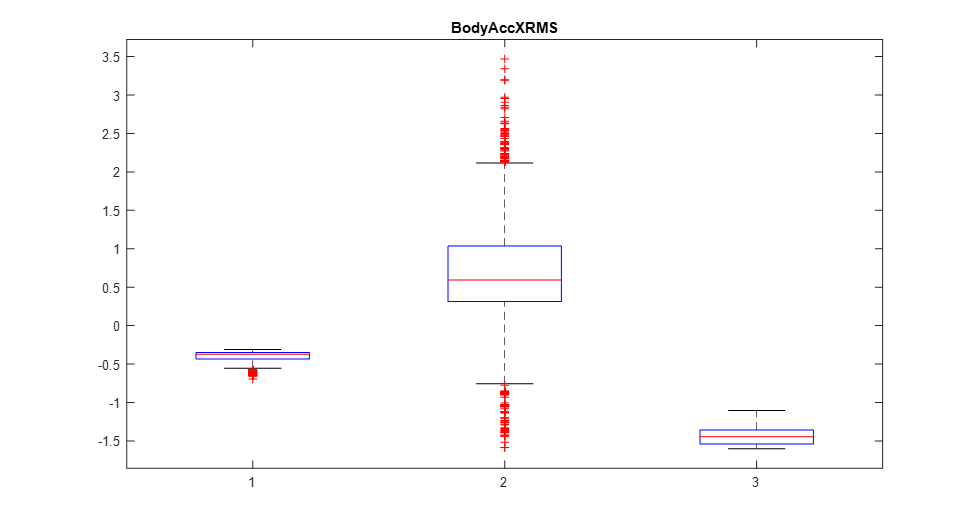

The negative value for BodyAccXRMS for cluster 3 might indicate 'laying' activity. Higher values of BodyAccXrms for cluster 2 indicate activity in motion. 

## Conclusion

Clustering involves a lot of trial and error. The right set of clusters will be different based on the goal of the application. Clustering may be employed for various reasons including data summarization, compression, efficiently finding nearest neighbors, identifying similar objects, removing outliers or labeling the data for supervised learning.  

*Copyright 2014-2019 MathWorks, Inc.*